# Introduction: Analysis

## System stablility

The system stability is decided by the roots of the system, if the roots are all on the LHS of the complex plane, then the system is stable under the Bounded Input Bounded Output criteria

% find the stability of the system
% pole command

s = tf('s');
G = 1/(s^2 + 2*s + 5);
pole(G)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i



% eig command
[A, B, C, D] = ssdata(G);
eig(A)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i


## First Order System

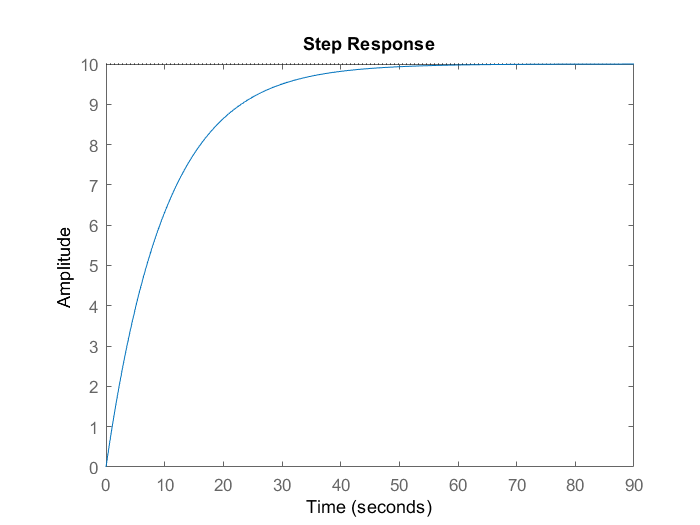

s = tf('s');

k_dc = 5; % dc gain
Tc = 10; % time constant
u = 2;

G = k_dc/(Tc*s + 1);

% step response
step(u*G)

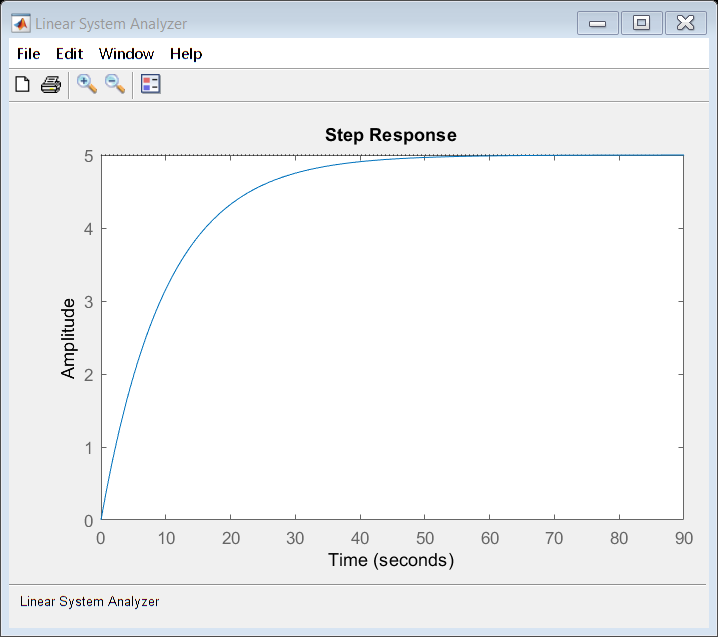


% using linear system analyzer to analyze the system
% one can also find it in the App section
linearSystemAnalyzer('step',G)

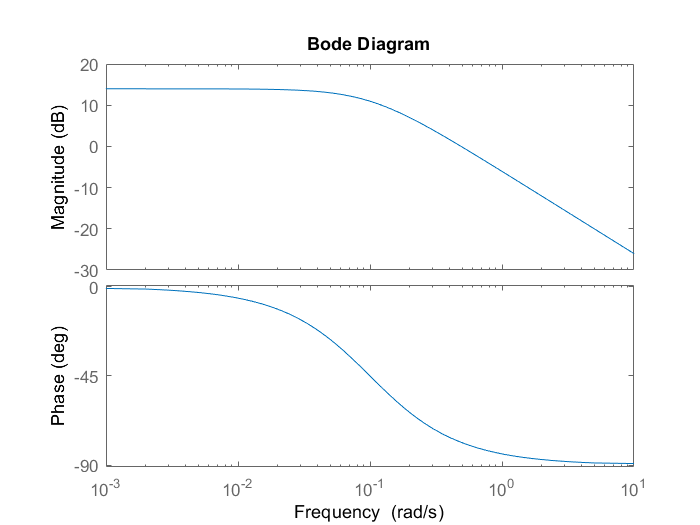


% bode plot
bode(G)

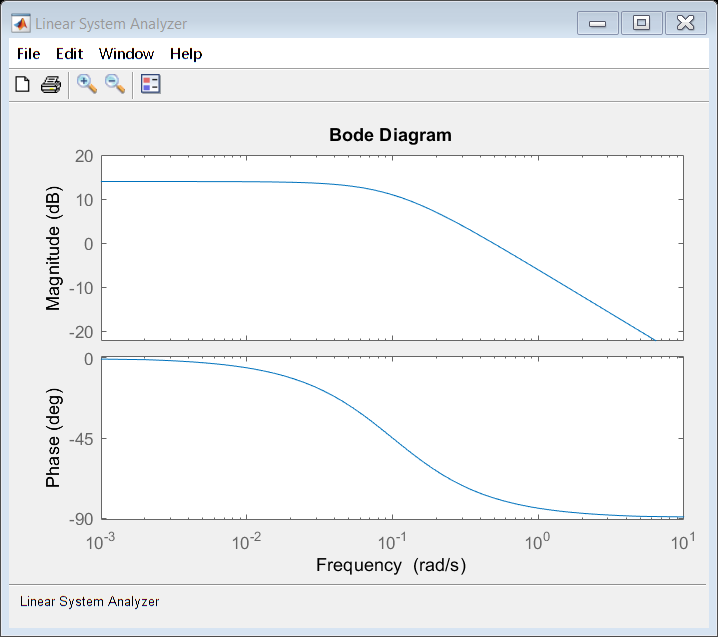

linearSystemAnalyzer('bode',G)

## Second Order system

% underdamped system
k_dc = 1;
w_n = 10;
zeta = 0.2;

s = tf('s');
G1 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G1)
axis([-3 1 -15 15])

step(G1)
axis([0 3 0 2])

% overdamped system
zeta = 1.2;

G2 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G2)
axis([-20 1 -1 1])

step(G2)
axis([0 1.5 0 1.5])

% critical damped system
zeta = 1;

G3 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G3)
axis([-11 1 -1 1])

step(G3)
axis([0 1.5 0 1.5])

% undamped system
zeta = 0;

G4 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G4)
axis([-1 1 -15 15])

step(G4)
axis([0 5 -0.5 2.5])

Bode plot

The magnitude of the bode plot of a second-order system drops off at -40 dB per decade in the limit, while the relative phase changes from 0 to -180 degrees. For underdamped systems, we also see a resonant peak near the natural frequency,  = 10 rad/s. The size and sharpness of the peak depends on the damping in the system, and is charaterized by the quality factor, or **Q-Factor**, defined below. The Q-factor is an important property in signal processing Q = 1/(2*zeta)

bode(G1,G2,G3,G4)
legend('underdamped: zeta < 1','overdamped: zeta > 1','critically-damped: zeta = 1','undamped: zeta = 0')